# LAB 3 

## 1)

### A)

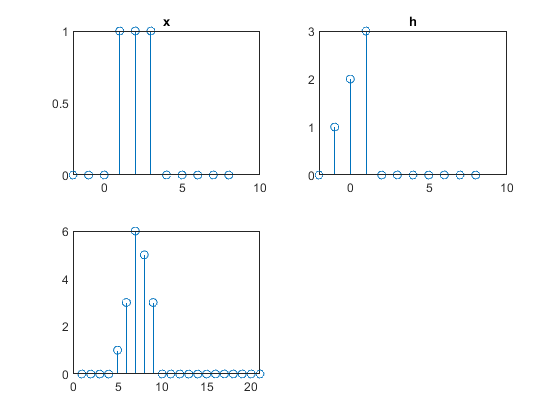


x=ones(1,11);
x(7:end)=0;
x(1,1:3)=0;
t=-2:1:8;
y=zeros(1,11);
y(1,2)=1;y(1,3)=2;y(1,4)=3;
figure(1)
subplot(2,2,1)
stem(t,x)
title('x');
subplot(2,2,2)
stem(t,y)
title('h');
z=conv(x,y);
subplot(2,2,3);
stem(z);

## B)

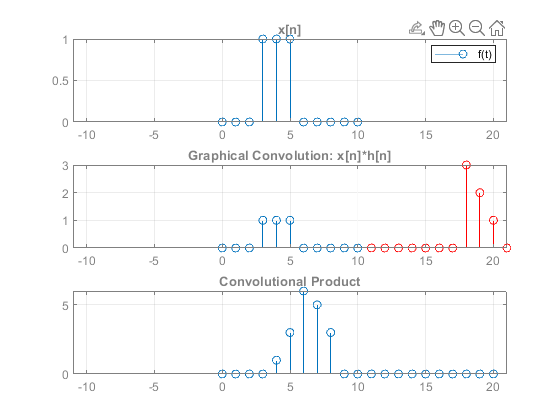

anime(x,y,[0:10],[0:10],1);

## C)


c=flip(x)'*flip(y);
[m,n]=size(c);
z=zeros(m,m+n-1);
for i=1:m
for j=1:m
z(i,j+i-1)=c(i,j);
end
end
for i=1:outlen(x,y)
z(1,i)=sum(z(:,i));
end
z=flip(z(1,:));
disp(z);

  Columns 1 through 15

     0     0     0     0     1     3     6     5     3     0     0     0     0     0     0

  Columns 16 through 21

     0     0     0     0     0     0



disp(conv(x,y));

  Columns 1 through 15

     0     0     0     0     1     3     6     5     3     0     0     0     0     0     0

  Columns 16 through 21

     0     0     0     0     0     0



## Task 2)

## A)

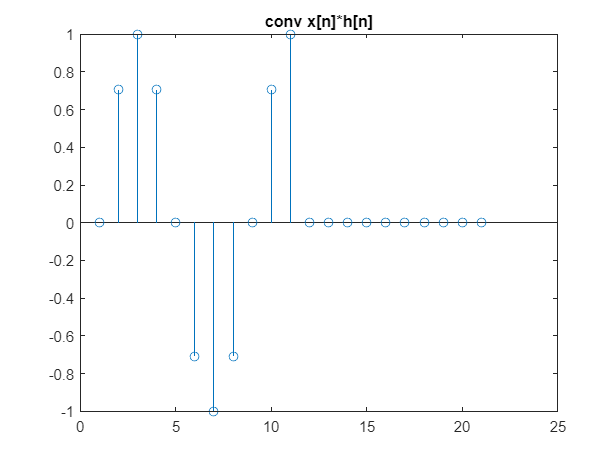


n=0:10;
x=zeros(size(n));
h=zeros(size(n));

x(1)=1;
h=sin(2*pi*n/8)*((ufunc(n)-ufunc(n-4)));
a1=conv(x,h);

figure(3);
stem(a1);
title('conv x[n]*h[n]');

## B)

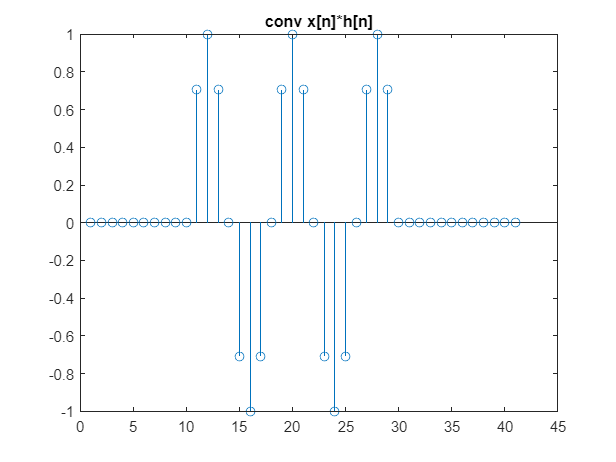

n=0:20;
x=zeros(size(n));
h=zeros(size(n));

x(10)=1;
h=sin(2*pi*n/8)*((ufunc(n)-ufunc(n-4)));
a2=conv(x,h);

stem(a2);
title('conv x[n]*h[n]');

## C)

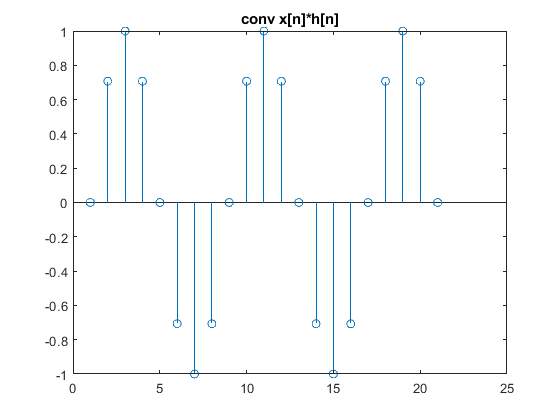

x=zeros(size(n));
h=zeros(size(n));

x=ufunc(n)-ufunc(n-4);
h=sin(2*pi*n/8)*((ufunc(n)-ufunc(n-4)));
a3=conv(x,h);

stem(a3);
title('conv x[n]*h[n]');

## D)

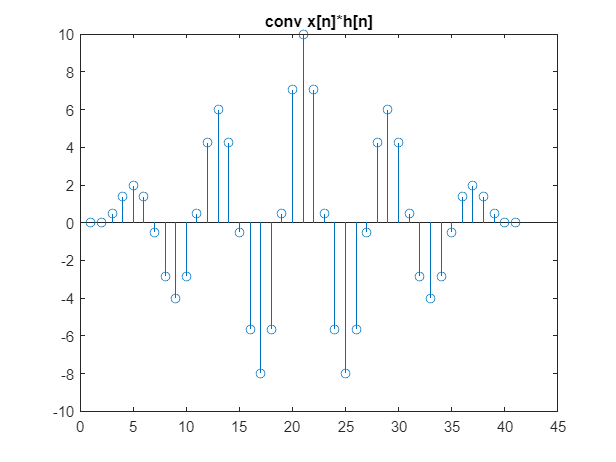


x=zeros(size(n));
h=zeros(size(n));

x=sin(2*pi*n/8);
h=sin(2*pi*n/8)*((ufunc(n)-ufunc(n-4)));
a4=conv(x,h);

stem(a4);
title('conv x[n]*h[n]');

## Task 3

## A)

y[n] satisfies the superposition principle therefore it is linear

y[n] is not a function of time so it is time invariant

y[n] does not depend on future values so it is casual

## B)

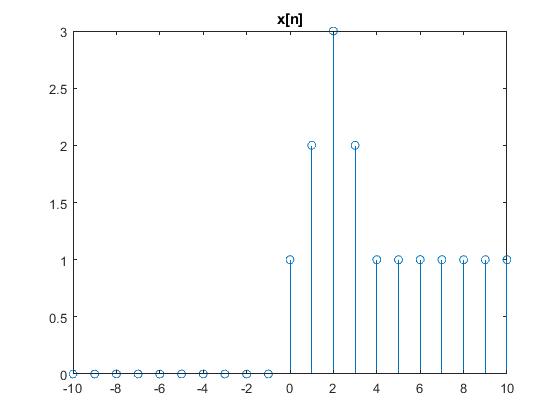

c=-10:10;
for n=1:length(c)
    if c(n)<0
        x(n)=0;
    else 
        if c(n)>=0 && c(n)<=2
            x(n)=c(n)+1;
       
        else 
            if c(n)>=3 && c(n)<=4
                x(n)=5-c(n);
            else
                if c(n)>=5
                    x(n)=1;
                end
            end
        end
    end
end

stem(c,x);
title('x[n]');

## C)

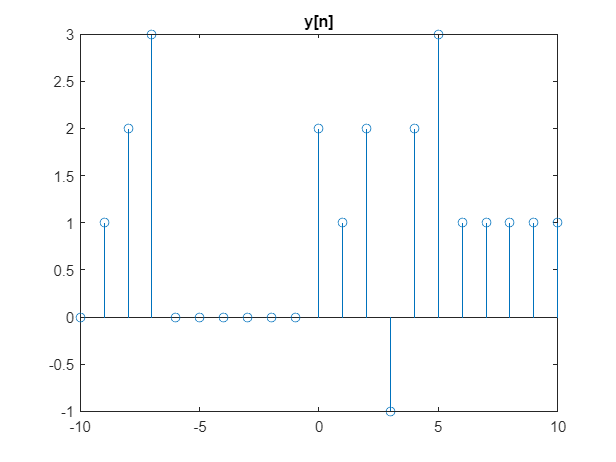

for n=11:1:21
    y(n)=(2*x(n)-3*x(n-1))+2*x(n-2);
end


stem(c,y);
title('y[n]')

## D)

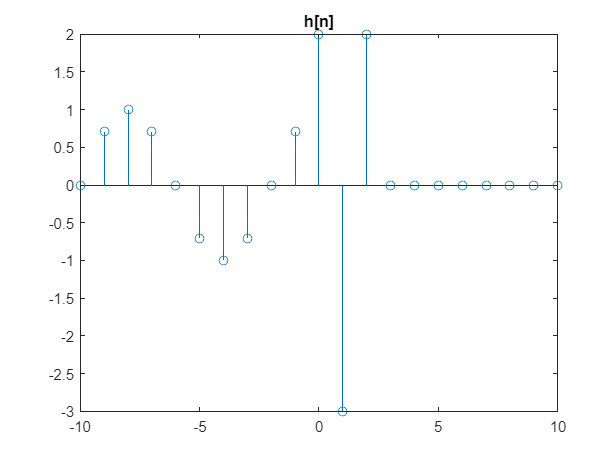

x=zeros(1,length(c));
x(11)=1;
for n=11:1:21
    h(n)=(2*x(n)-3*x(n-1))+2*x(n-2);
end

stem(c,h);
title('h[n]')

## E)

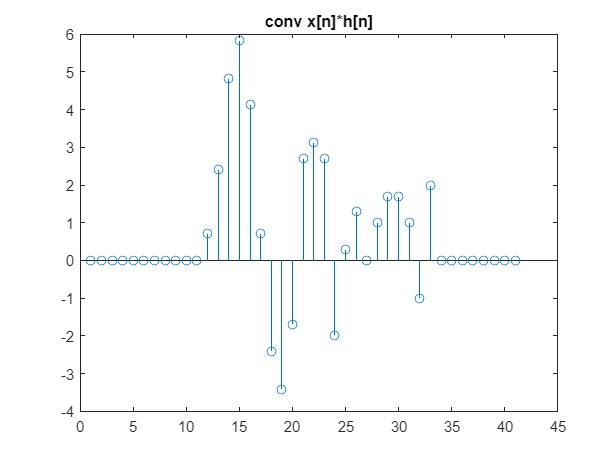

figure(9)
for n=11:1:21
    h(n)=(2*x(n)-3*x(n-1))+2*x(n-2);
end
for n=11:1:21
    if c(n)<0
        x(n)=0;
    else 
        if c(n)>=0 && c(n)<=2
            x(n)=c(n)+1;
       
        else 
            if c(n)>=3 && c(n)<=4
                x(n)=5-c(n);
            else
                if c(n)>=5
                    x(n)=1;
                end
            end
        end
    end
end
stem(conv(x,h));
title('conv x[n]*h[n]')